# Dummy-coded maps for cue encoding

Model (CESeO)

- parameter: 

-     1 **C**ue onset 

-     0 **E**xpectationRating onset 

-     0 **S**timulus onset 

-     0          pmod: **e**xpectation rating (angle)

-     0 **O**utcomeRating onset

- Motion covariate: 24DOF + CSF

- Spike combined into one regressor (Incorrect)

# Pain Cue only (dummy-coded; pain cue > rest)

#### Pain Cue only :: load dataset

clear all;
close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0013.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel/sub-0014/con_0013.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 29951100 bytes
Loading image number:    75
Elapsed time is 14.550953 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7164195  Bit rate: 22.77 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXexpect_P', 'stimXexpect_V', 'stimXexpect_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXexpect_P', 'simple_stimXexpect_V', 'simple_stimXexpect_C'};

#### Pain Cue only :: `check data coverage`

m = mean(con_data_obj);e
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              19:08:37 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Pain Cue only :: Plot diagnostics, before l2norm

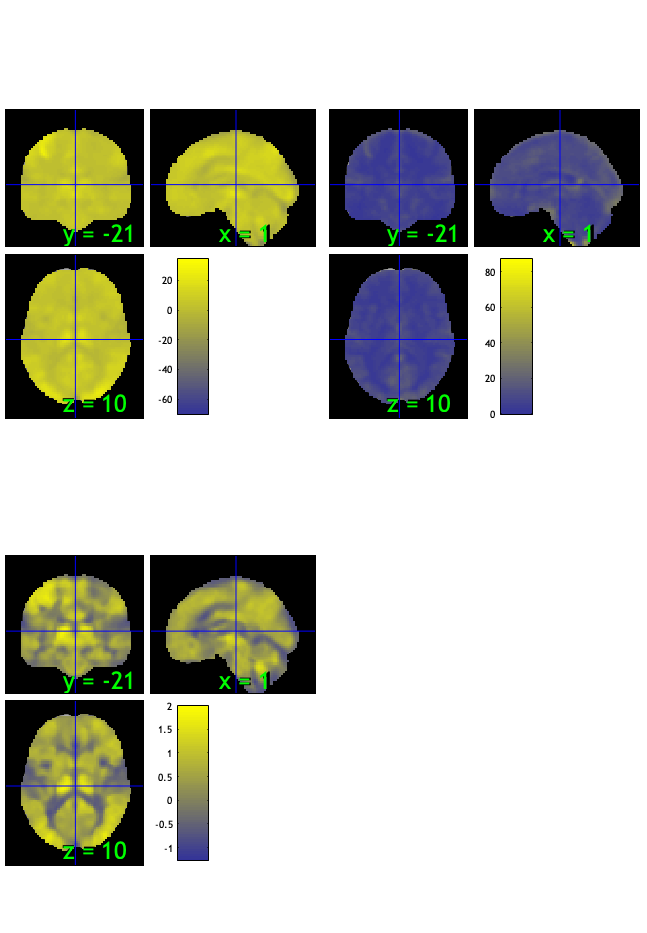

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.33%
Expected 3.75 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 48 
Uncorrected: 8 images		Cases 20 23 45 46 48 59 72 74 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 41.33%
Expected 3.75 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 2 
Uncorrected: 6 images		Cases 2 32 41 43 67 73 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                   

SPM12: spm_check_registration (v7759)              19:09:09 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

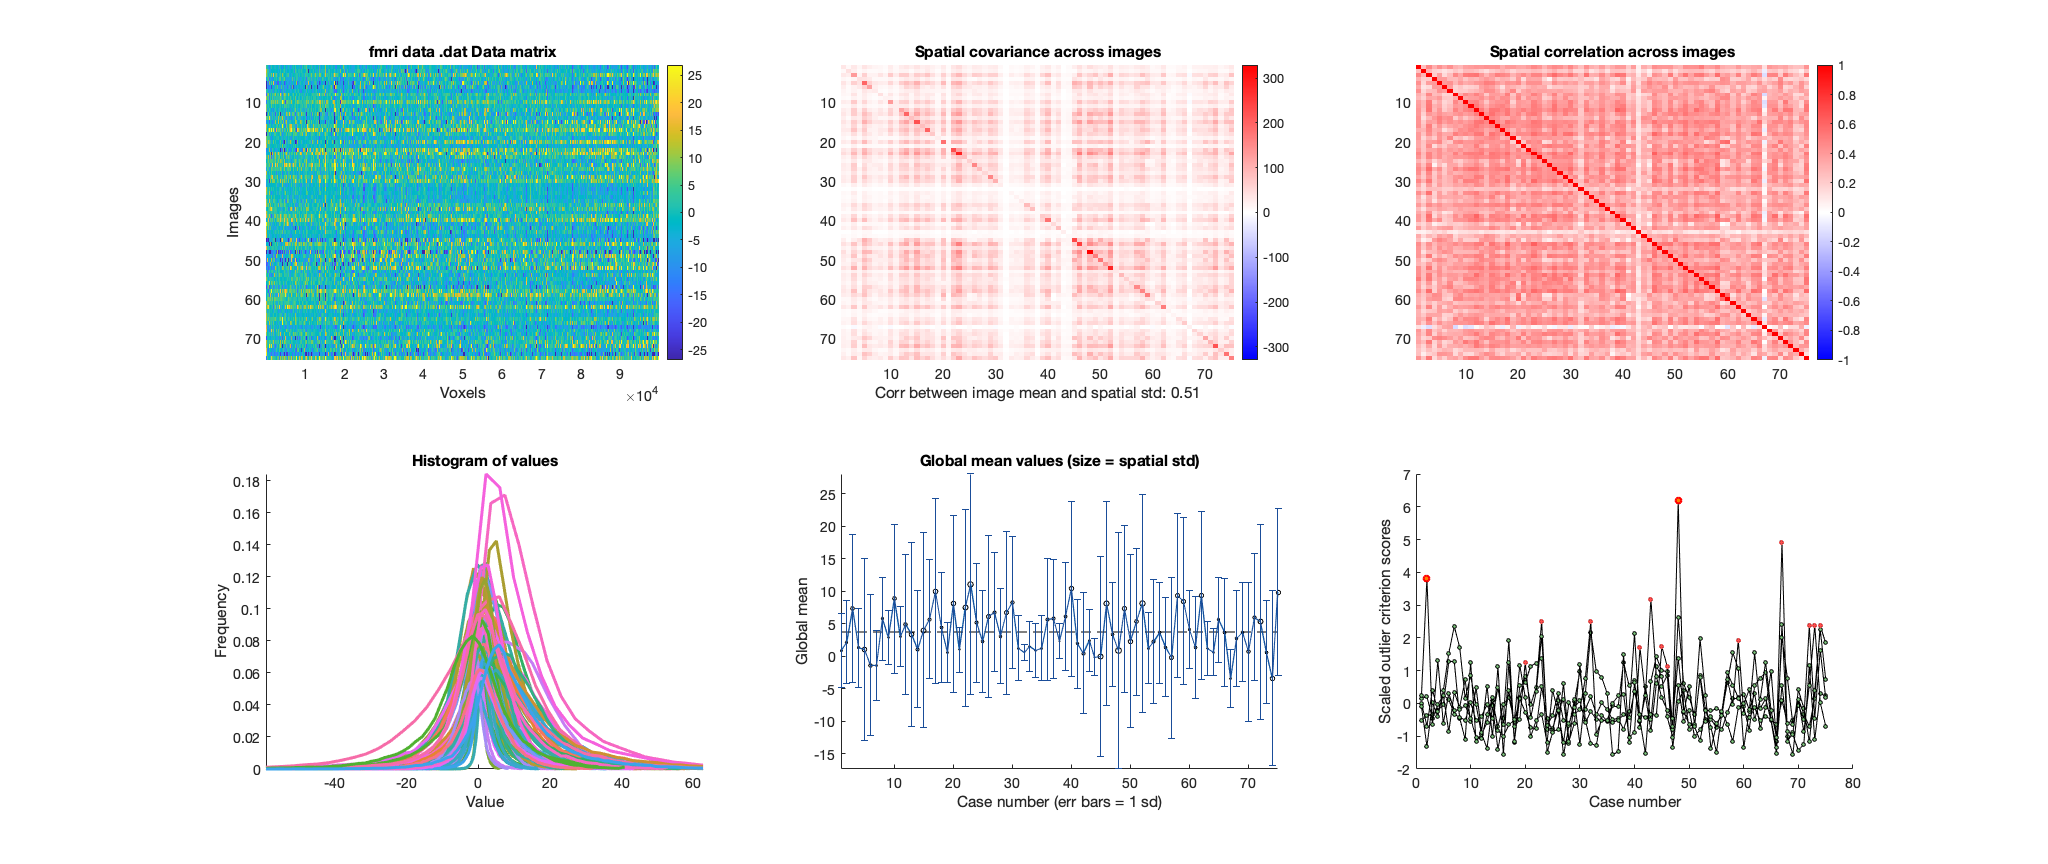

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain Cue only :: run robfit

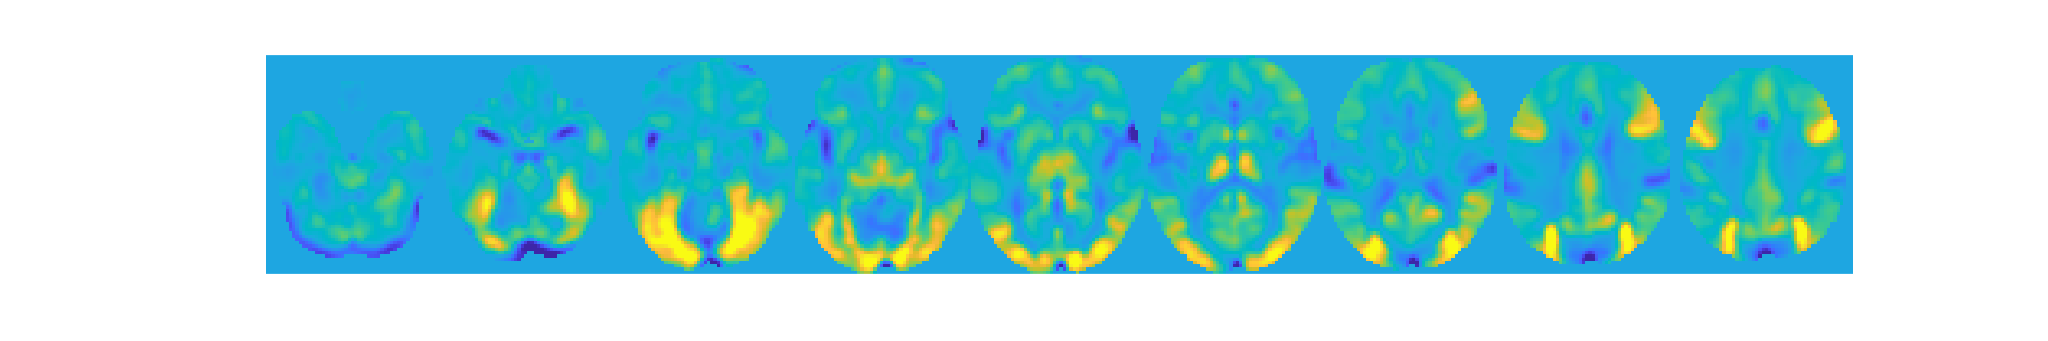

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain Cue only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 75


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 2 participants, size is now 73


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0015"    "participants that are outliers:... sub-0091"



disp(n);

    {'sub-0015'}    {'sub-0091'}



#### Pain Cue only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain Cue only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


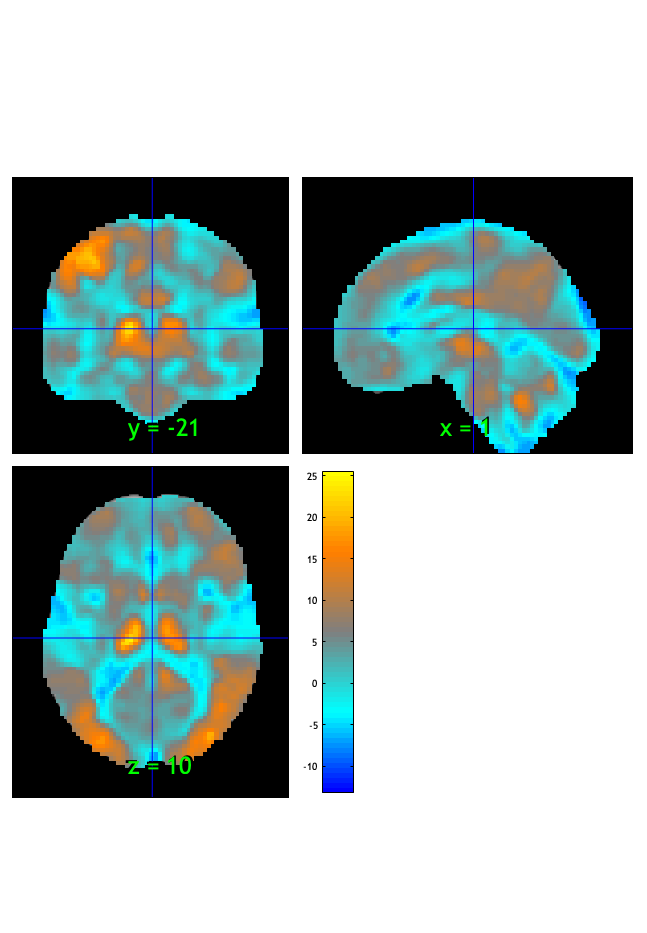

SPM12: spm_check_registration (v7759)              19:09:14 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.036754

Image   1
 33 contig. clusters, sizes   1 to 73005
Positive effect: 63739 voxels, min p-value: 0.00000000
Negative effect: 9657 voxels, min p-value: 0.00000000


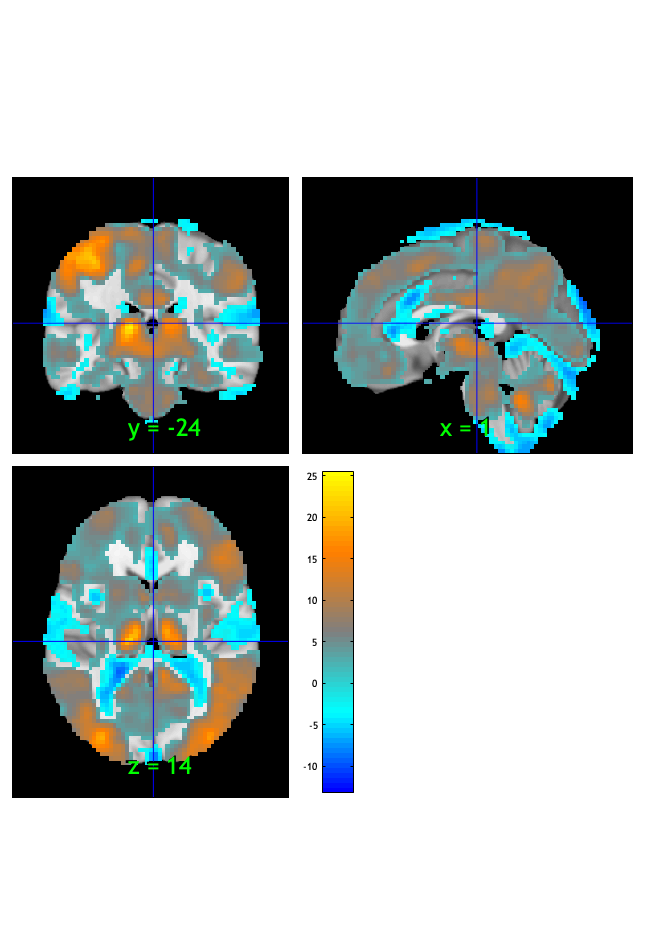

SPM12: spm_check_registration (v7759)              19:09:16 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000564

Image   1
 30 contig. clusters, sizes   1 to 55909
Positive effect: 51321 voxels, min p-value: 0.00000000
Negative effect: 5036 voxels, min p-value: 0.00000000


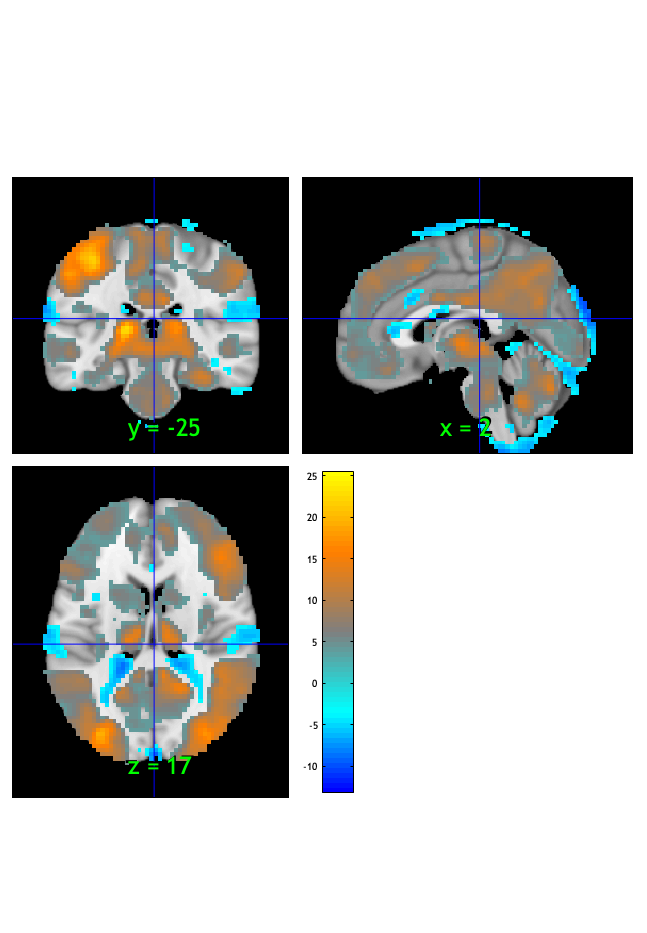

SPM12: spm_check_registration (v7759)              19:09:18 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


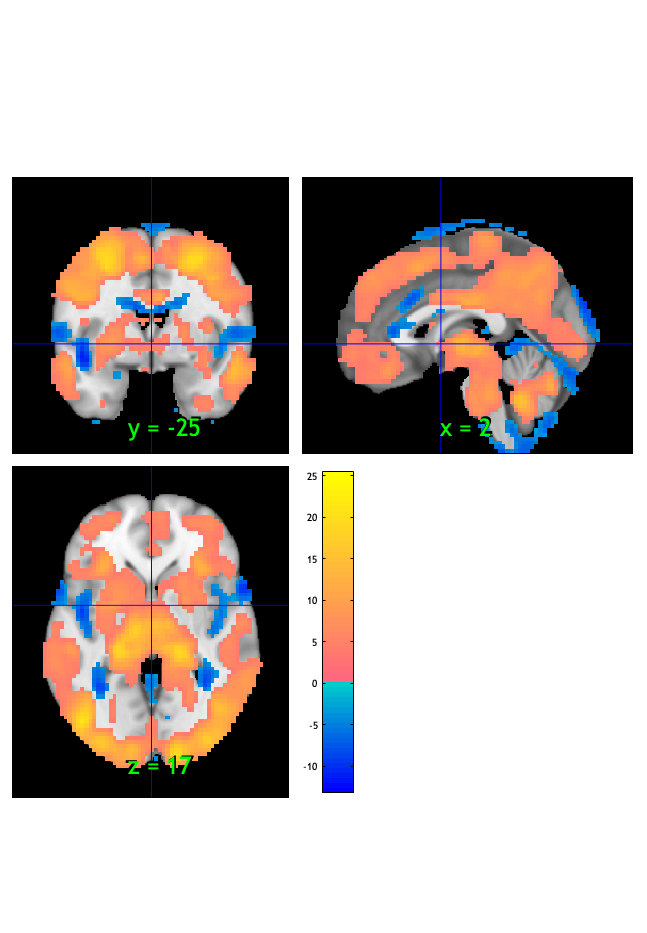

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1301 voxels displayed, 55056 not displayed on these slices


sagittal montage: 1390 voxels displayed, 54967 not displayed on these slices


sagittal montage: 1331 voxels displayed, 55026 not displayed on these slices


axial montage: 10315 voxels displayed, 46042 not displayed on these slices


axial montage: 11490 voxels displayed, 44867 not displayed on these slices


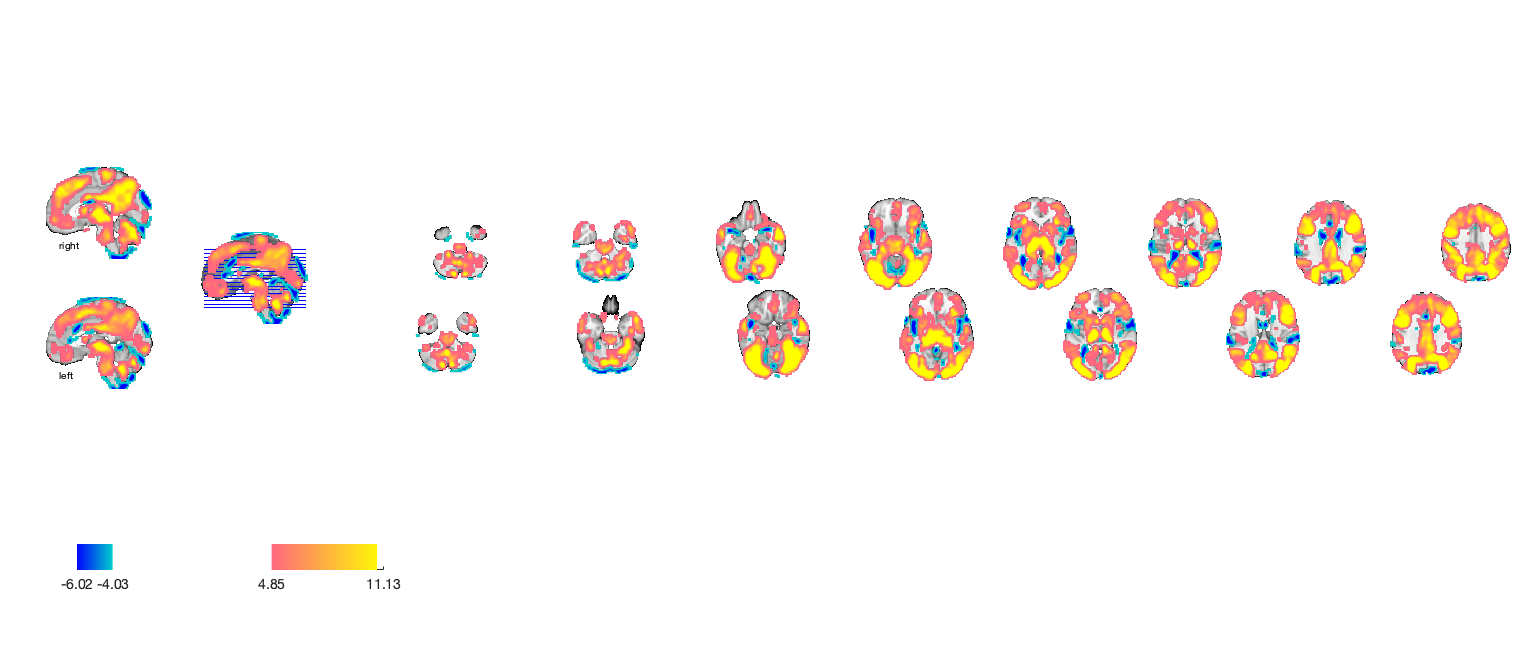

drawnow, snapnow;

#### Pain Cue only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high       words_high   
    _________    _______________    __________    ________________

     -0.3063     {'anxiety'    }     0.43533      {'visual'      }
    -0.29236     {'trait'      }     0.38069      {'object'      }
    -0.28382     {'disorder'   }     0.36996      {'objects'     }
    -0.28093     {'age'        }     0.33332      {'attention'   }
    -0.27561     {'rating'     }     0.31964      {'solving'     }
    -0.27473     {'pain'       }     0.30946      {'calculation' }
    -0.27331     {'sensation'  }     0.30224      {'rotation'    }
    -0.26541     {'affect'     }     0.30216      {'shape'       }
    -0.26252     {'stimulation'}     0.29884      {'orthographic'}
     -0.2606     {'affe

#### **Pain Cue only :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.1606	-25.4783	0.0000	1.0000	
Cog Wholebrain	0.0307	8.9744	0.0000	1.0000	
Emo Wholebrain	0.1245	20.9741	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.16056      0.006207    -25.867    2.2204e-15    -3.0275 
    {'Cog Wholebrain' }     0.030713     0.0034203     8.9797    2.2782e-13      1.051 
    {'Emo Wholebrain' }      0.12448     0.0058796     21.172    2.2204e-15      2.478 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {73×3 cell}
        text_han: {73×3 cell}
       point_han: {73×3 cell}
    star_handles: [9.0015 10.0015 11.0015]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.14697     0.0061867    -23.756    2.2204e-15    -2.7805 
    {'Cog Wholebrain' }     0.029853     0.0031711     9.4141    3.5527e-14     1.1018 
    {'Emo Wholebrain' }      0.11335     0.0057763     19.624    2.2204e-15     2.2968 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {73×3 cell}
        text_han: {73×3 cell}
       point_han: {73×3 cell}
    star_handles: [12.0015 13.0015 14.0015]


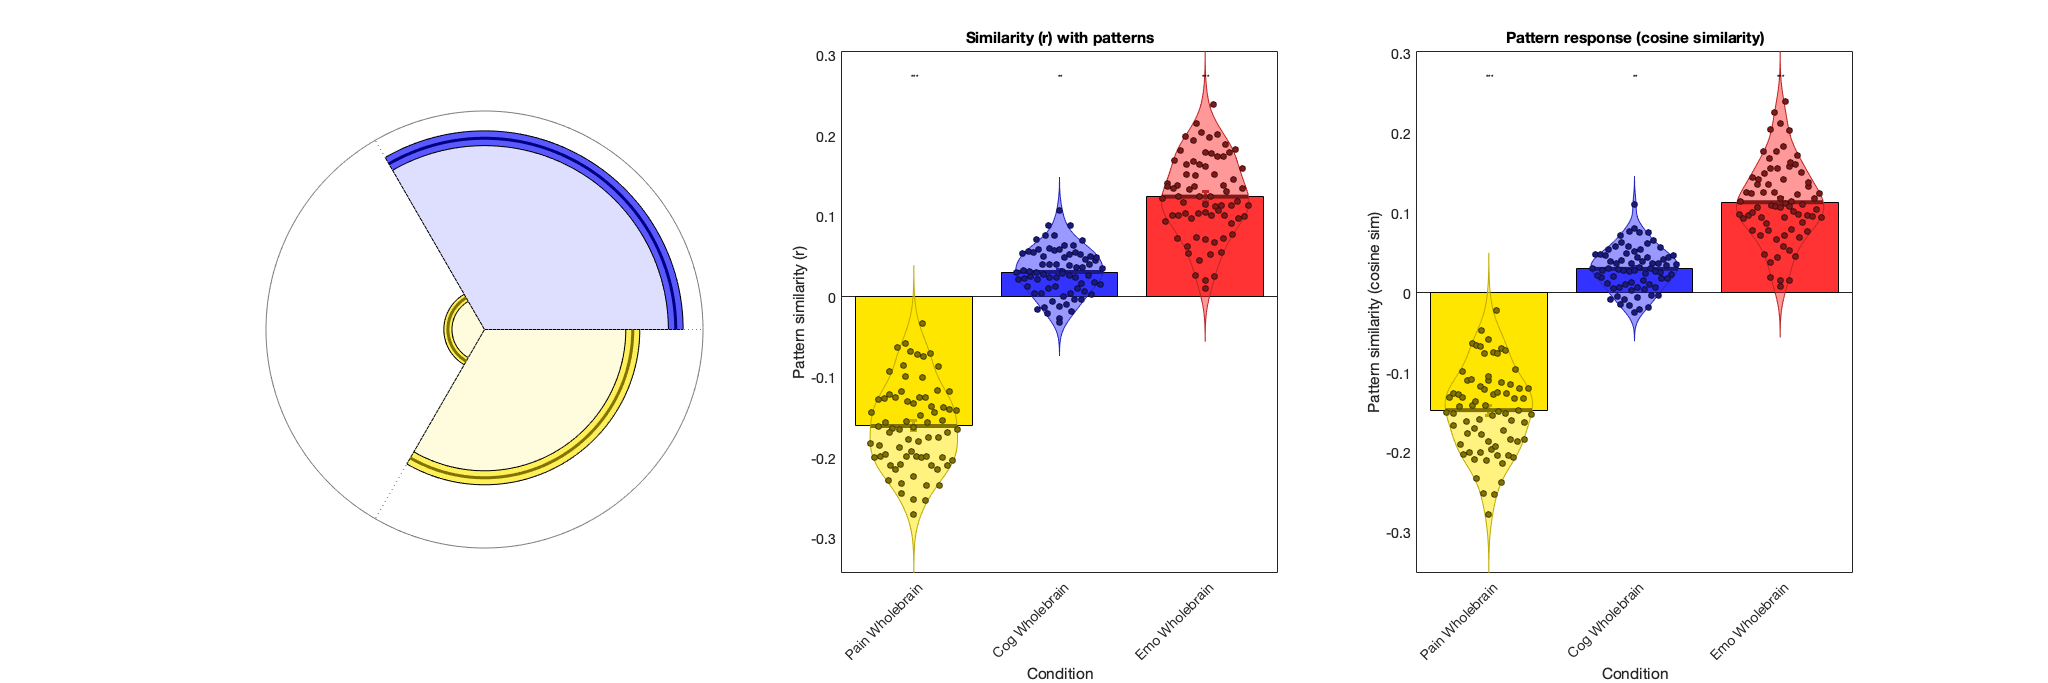

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious Cue only (dummy-coded; Vicarious Cue > rest)

#### Vicarious Cue only :: load dataset

clear all;
close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0014.nii'));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel/sub-0014/con_0014.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 29951100 bytes
Loading image number:    75
Elapsed time is 9.918197 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7196241  Bit rate: 22.78 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXexpect_P', 'stimXexpect_V', 'stimXexpect_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXexpect_P', 'simple_stimXexpect_V', 'simple_stimXexpect_C'};

#### Vicarious Cue only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              19:12:15 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious Cue only :: Plot diagnostics, before l2norm

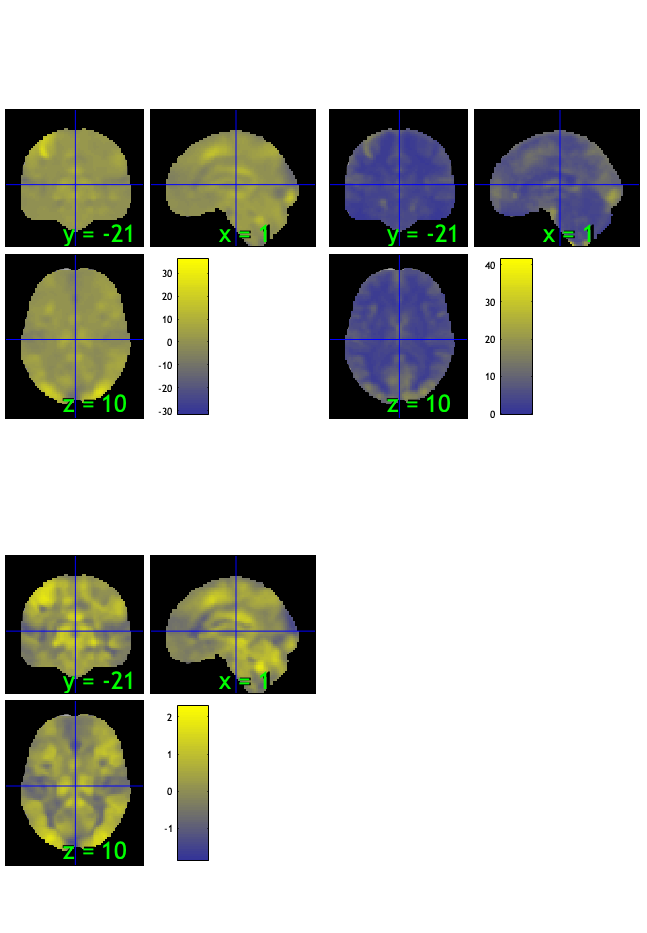

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 30.67%
Expected 3.75 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 22 72 
Uncorrected: 8 images		Cases 18 22 23 27 46 52 72 75 

Retained 21 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 41.33%
Expected 3.75 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 2 67 
Uncorrected: 8 images		Cases 2 4 38 43 44 63 67 68 

Mahalanobis (cov and corr, q<0.05 corrected):
  4 images 
                               Outlier_count    Percentage
        

SPM12: spm_check_registration (v7759)              19:12:47 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

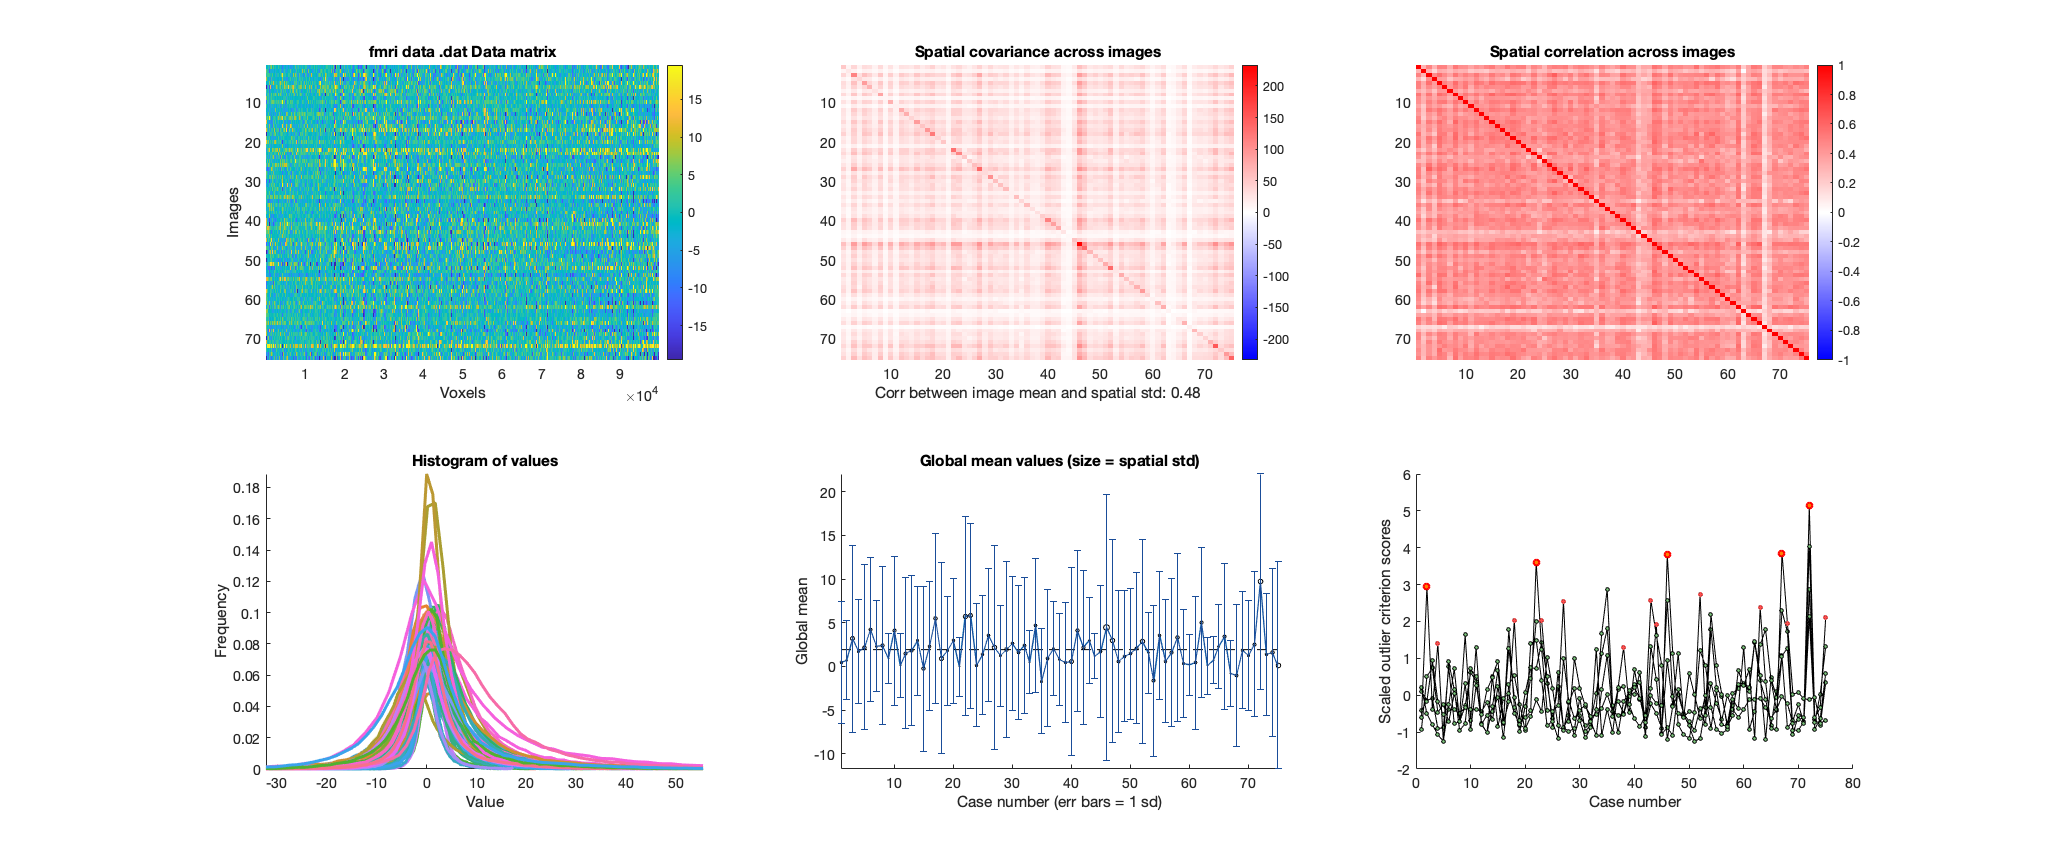

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious Cue only :: run robfit

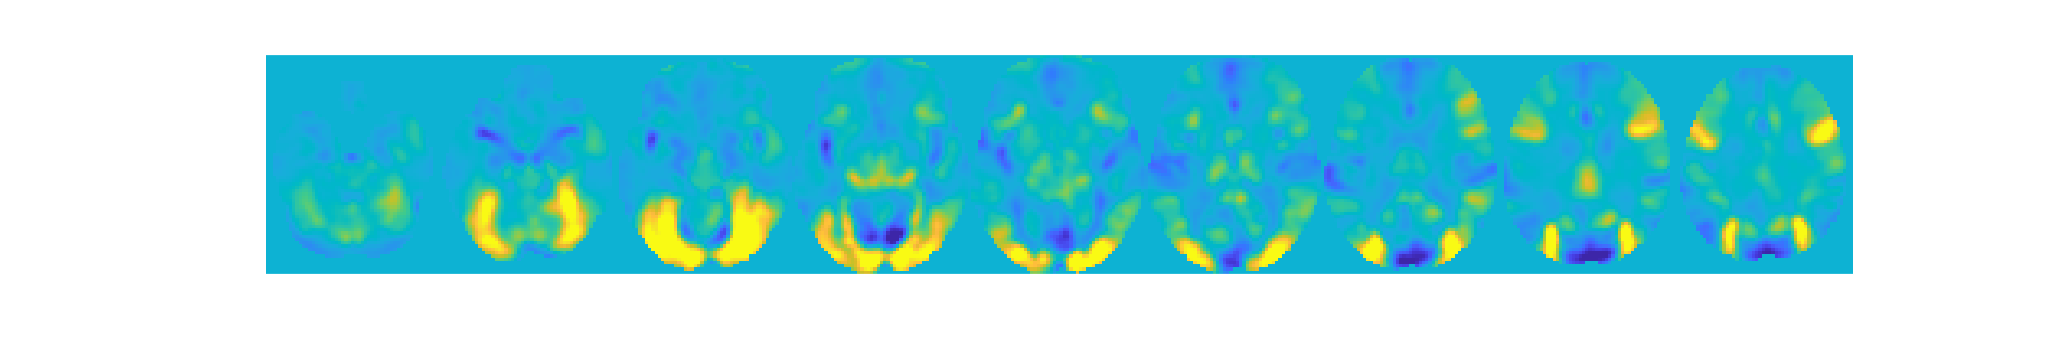

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious Cue only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 75


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 5 participants, size is now 70


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"



disp(n);

    {'sub-0015'}    {'sub-0051'}    {'sub-0088'}    {'sub-0123'}    {'sub-0129'}



#### Vicarious Cue only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious Cue only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


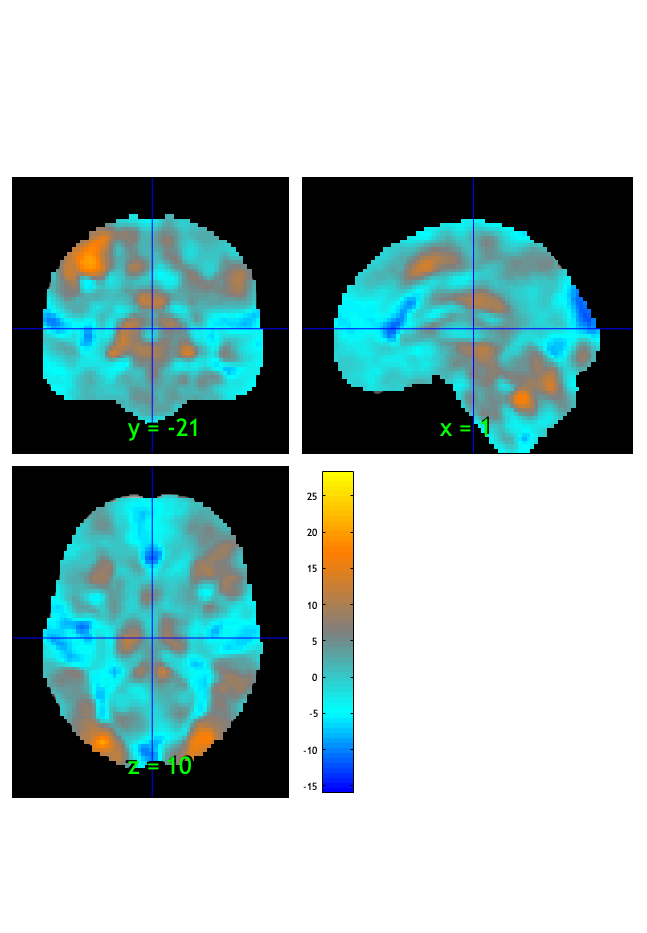

SPM12: spm_check_registration (v7759)              19:12:52 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.031253

Image   1
 30 contig. clusters, sizes   1 to 62024
Positive effect: 42852 voxels, min p-value: 0.00000000
Negative effect: 19566 voxels, min p-value: 0.00000000


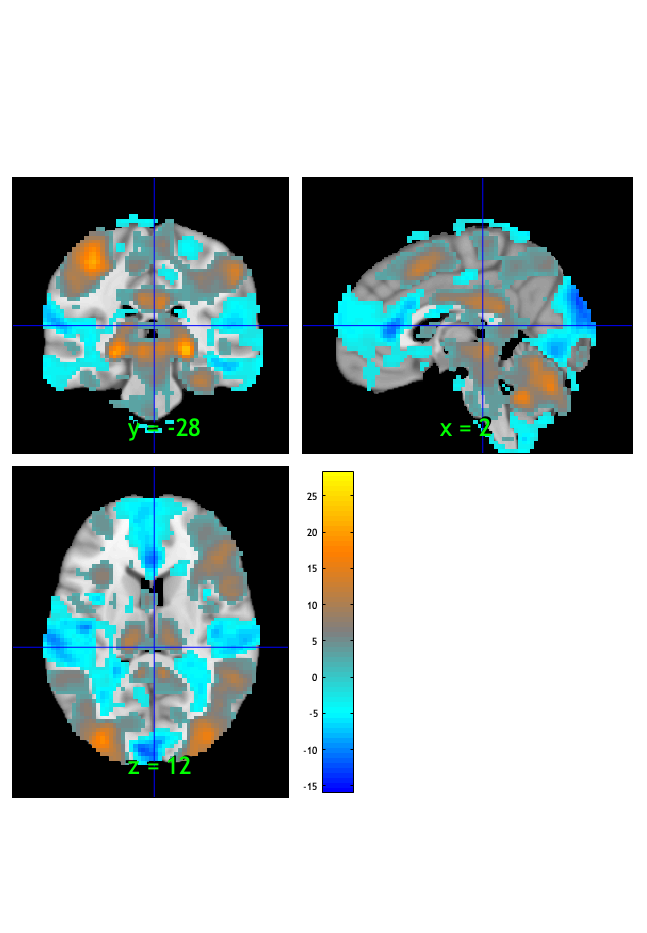

SPM12: spm_check_registration (v7759)              19:12:54 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


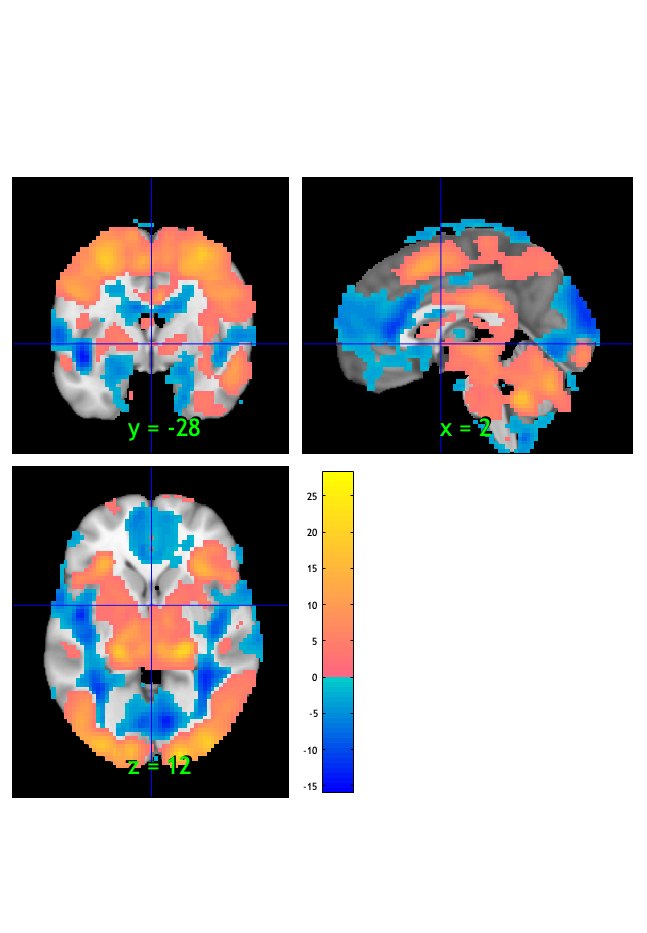

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1575 voxels displayed, 60843 not displayed on these slices


sagittal montage: 1486 voxels displayed, 60932 not displayed on these slices


sagittal montage: 1460 voxels displayed, 60958 not displayed on these slices


axial montage: 11673 voxels displayed, 50745 not displayed on these slices


axial montage: 12686 voxels displayed, 49732 not displayed on these slices


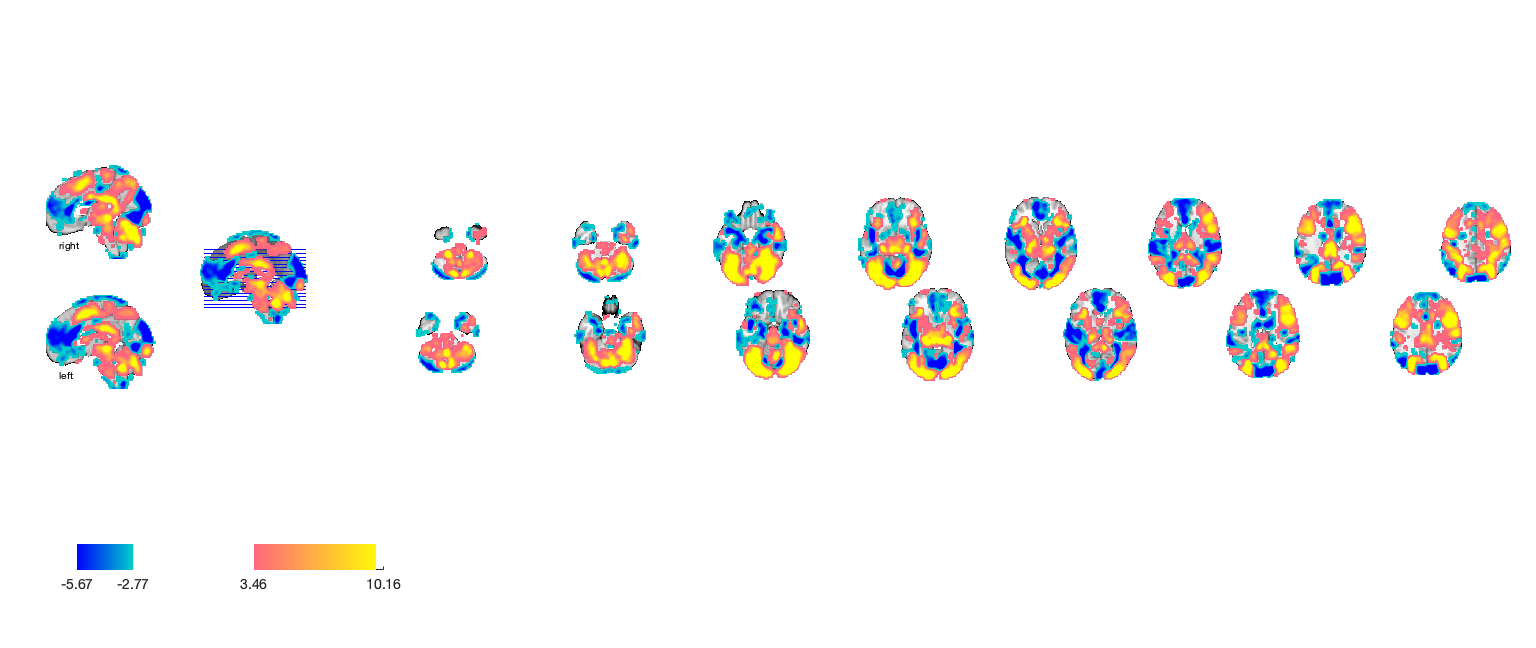

drawnow, snapnow;

#### Vicarious Cue only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low     words_low      testr_high       words_high   
    _________    ____________    __________    ________________

    -0.35807     {'rating'  }     0.48312      {'visual'      }
    -0.34663     {'trait'   }     0.39845      {'object'      }
     -0.3193     {'anxiety' }     0.38463      {'objects'     }
    -0.31872     {'negative'}     0.33139      {'attention'   }
    -0.30582     {'positive'}     0.32531      {'rotation'    }
    -0.30271     {'disorder'}      0.3222      {'shape'       }
    -0.29958     {'ratings' }      0.3131      {'letter'      }
    -0.29735     {'affect'  }     0.28008      {'visuospatial'}
    -0.29459     {'age'     }     0.27754      {'orthographic'}
    -0.29055     {'personal'}     0.27679      {'naming'

Vicarious Cue only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.1409	-23.0372	0.0000	1.0000	
Cog Wholebrain	0.0232	6.2278	0.0000	1.0000	
Emo Wholebrain	0.1126	18.0891	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.14088     0.0060401    -23.323    2.2204e-15    -2.7877 
    {'Cog Wholebrain' }     0.023162     0.0037167     6.2318    3.1807e-08    0.74484 
    {'Emo Wholebrain' }      0.11261     0.0061816     18.217    2.2204e-15     2.1773 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {70×3 cell}
        text_han: {70×3 cell}
       point_han: {70×3 cell}
    star_handles: [9.0016 10.0016 11.0016]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.13624     0.0059953    -22.724    2.2204e-15    -2.7161 
    {'Cog Wholebrain' }     0.022525     0.0035854     6.2824    2.5865e-08    0.75089 
    {'Emo Wholebrain' }      0.10981     0.0062431      17.59    2.2204e-15     2.1024 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {70×3 cell}
        text_han: {70×3 cell}
       point_han: {70×3 cell}
    star_handles: [12.0016 13.0016 14.0016]


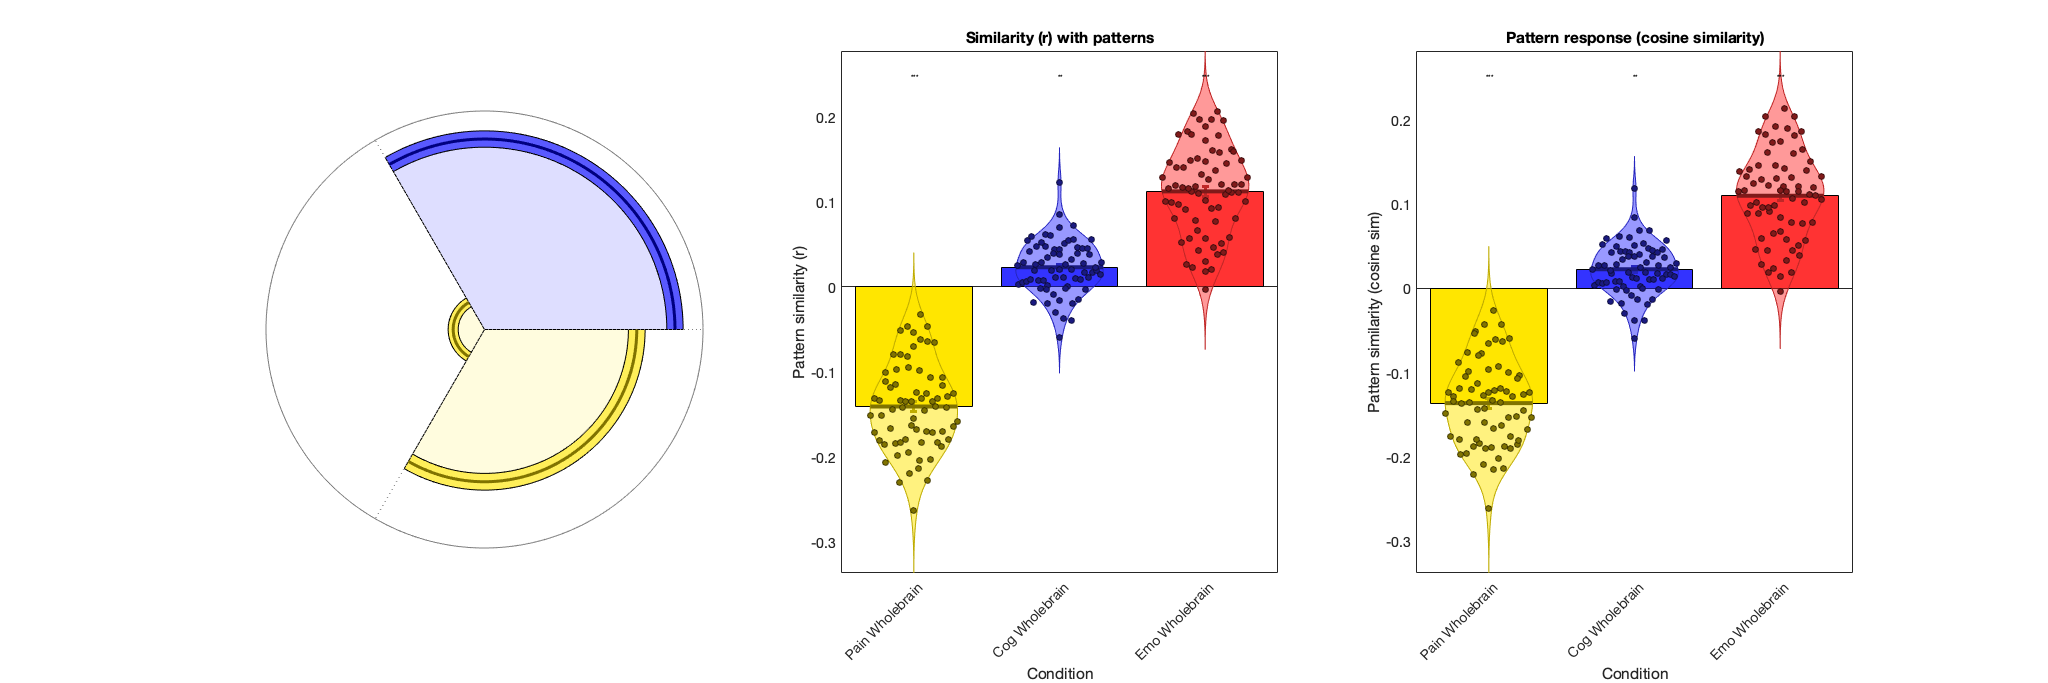

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive Cue only (dummy-coded; Cognitive Cue > rest)

#### Cognitive Cue only :: load dataset

clear all;
close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0015.nii'));
spm('Defaults','fMRI');
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESeO/1stLevel/sub-0014/con_0015.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 29951100 bytes
Loading image number:    75
Elapsed time is 12.905863 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7198220  Bit rate: 22.78 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXexpect_P', 'stimXexpect_V', 'stimXexpect_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXexpect_P', 'simple_stimXexpect_V', 'simple_stimXexpect_C'};

#### Cognitive Cue only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              19:14:49 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Cognitive Cue only :: Plot diagnostics, before l2norm

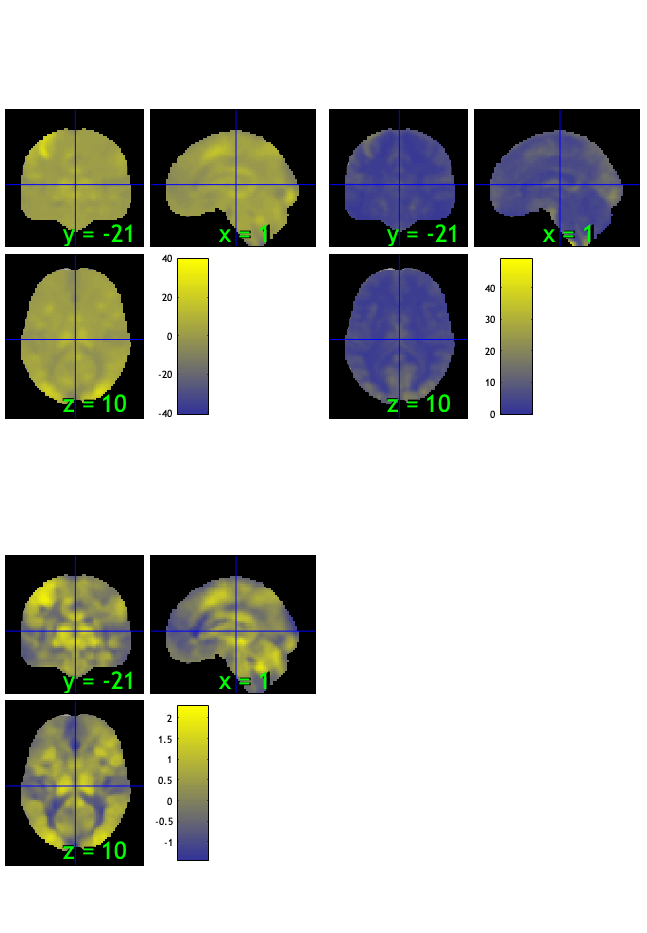

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.33%
Expected 3.75 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 29 46 
Uncorrected: 8 images		Cases 3 4 14 29 42 46 48 72 

Retained 14 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.33%
Expected 3.75 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 9 43 44 
Uncorrected: 7 images		Cases 4 9 43 44 45 63 68 

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
          

SPM12: spm_check_registration (v7759)              19:15:20 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

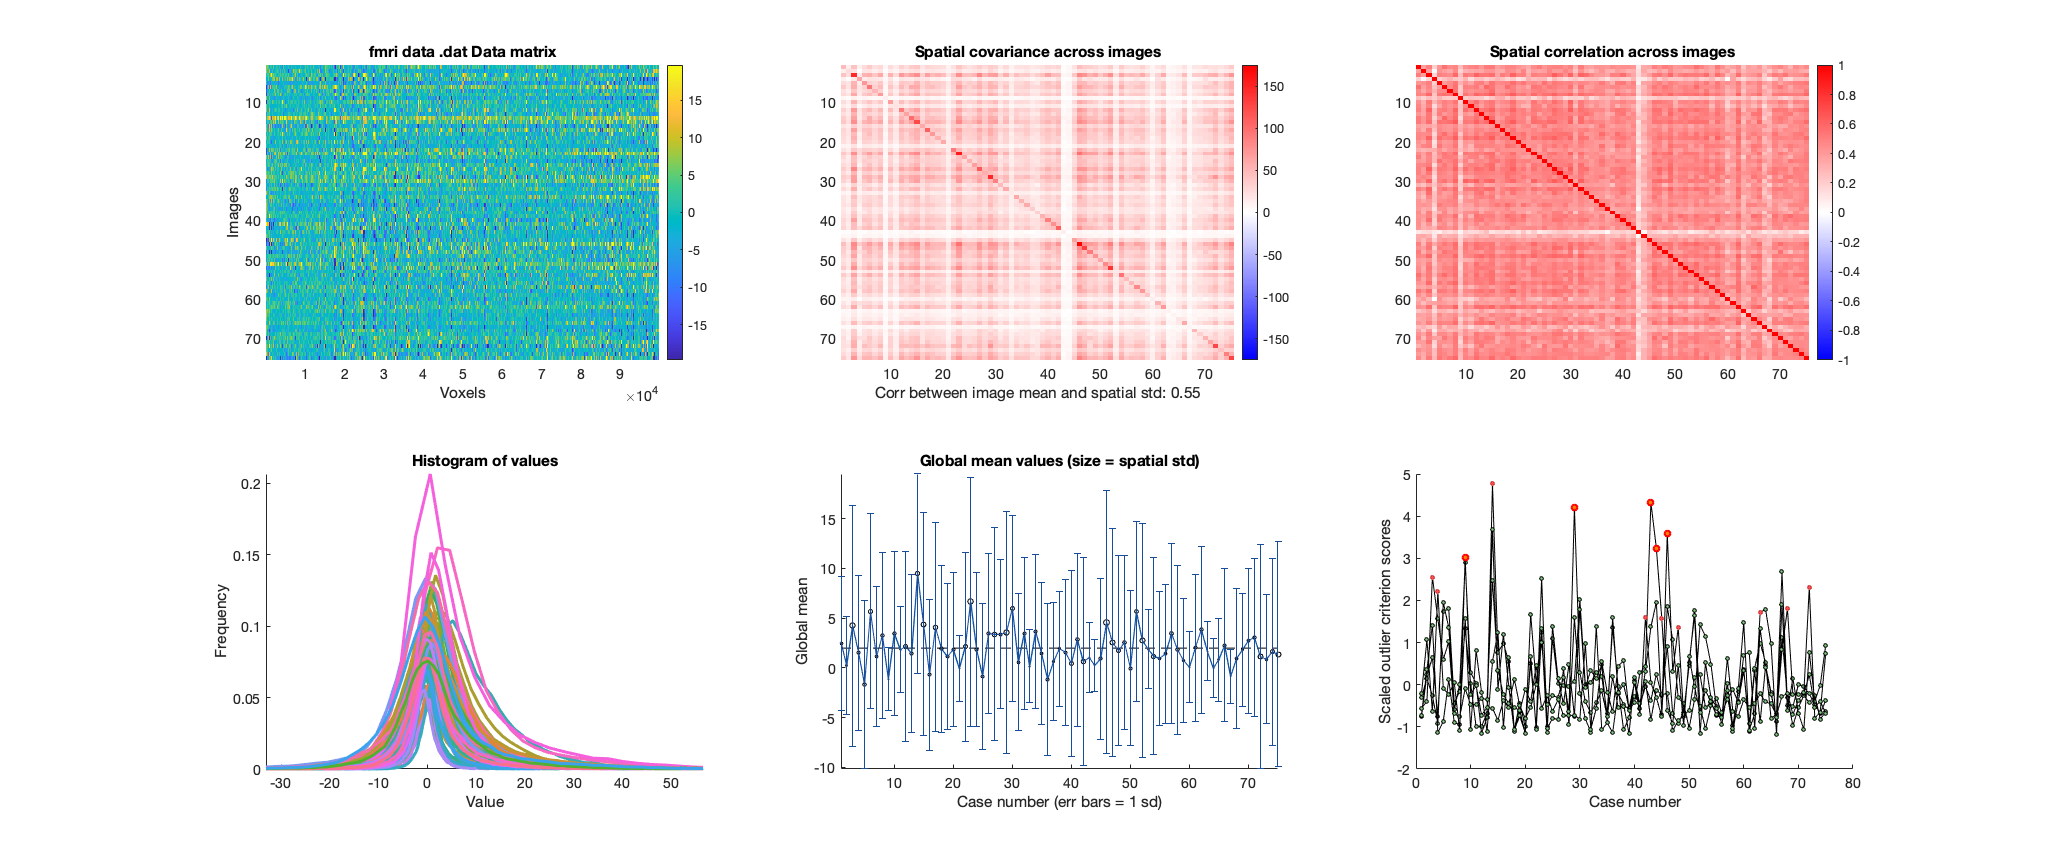

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive Cue only :: run robfit

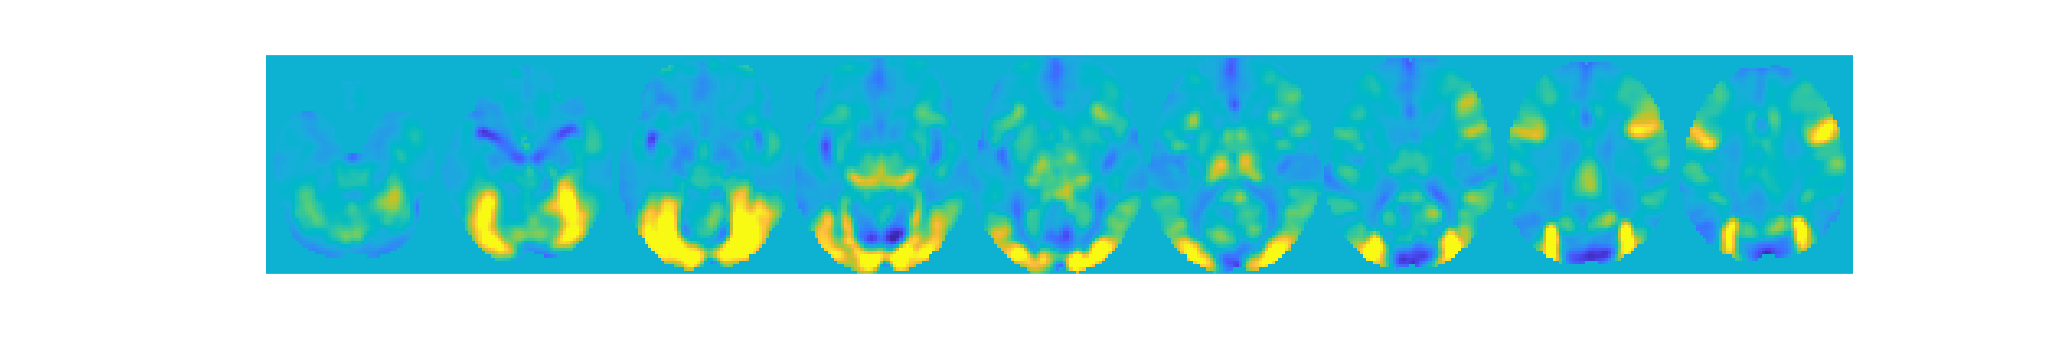

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive Cue only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 75


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 5 participants, size is now 70


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"    "participants that are outliers:... sub-…"



disp(n);

    {'sub-0028'}    {'sub-0061'}    {'sub-0082'}    {'sub-0085'}    {'sub-0088'}



#### Cognitive Cue only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive Cue only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


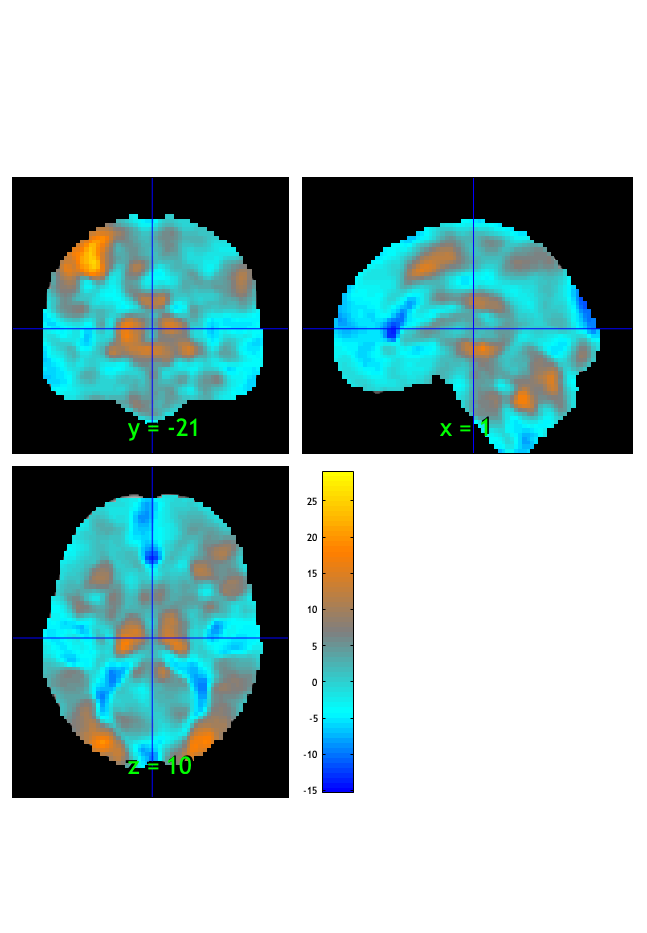

SPM12: spm_check_registration (v7759)              19:15:26 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.032509

Image   1
 26 contig. clusters, sizes   1 to 64529
Positive effect: 43010 voxels, min p-value: 0.00000000
Negative effect: 21908 voxels, min p-value: 0.00000000


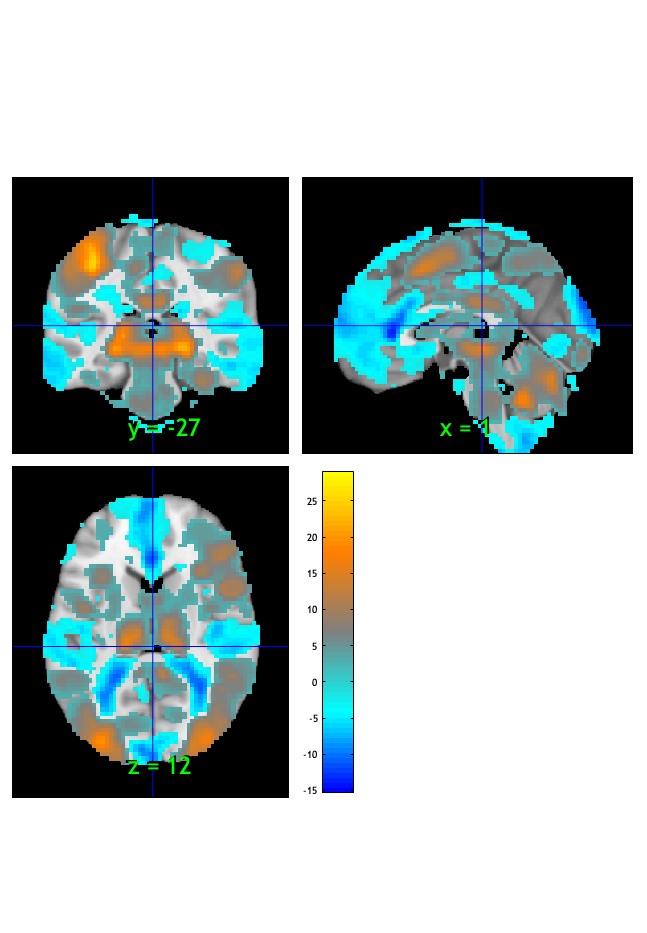

SPM12: spm_check_registration (v7759)              19:15:27 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


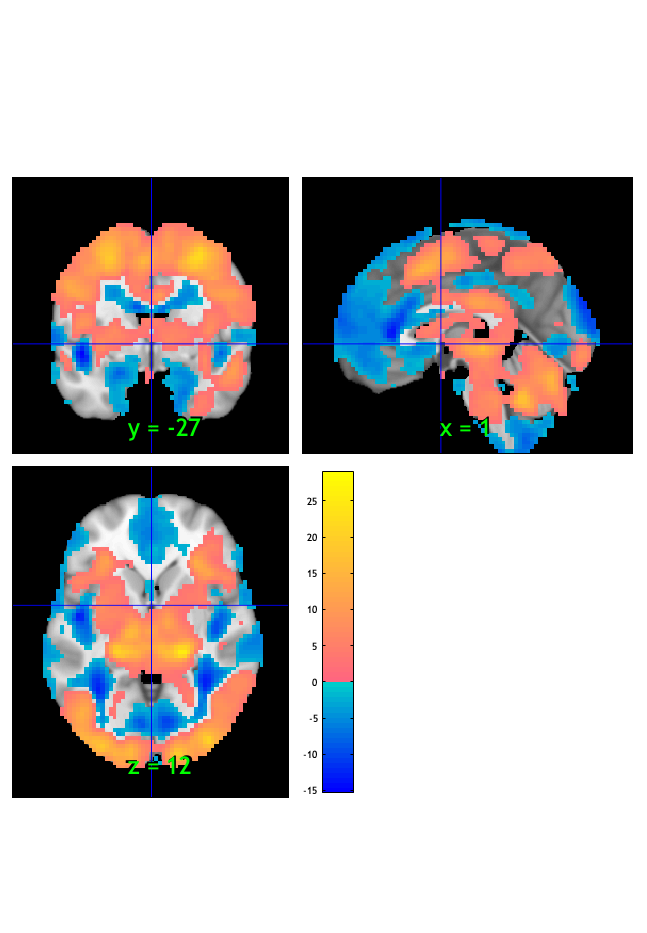

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1752 voxels displayed, 63166 not displayed on these slices


sagittal montage: 1621 voxels displayed, 63297 not displayed on these slices


sagittal montage: 1613 voxels displayed, 63305 not displayed on these slices


axial montage: 11977 voxels displayed, 52941 not displayed on these slices


axial montage: 13101 voxels displayed, 51817 not displayed on these slices


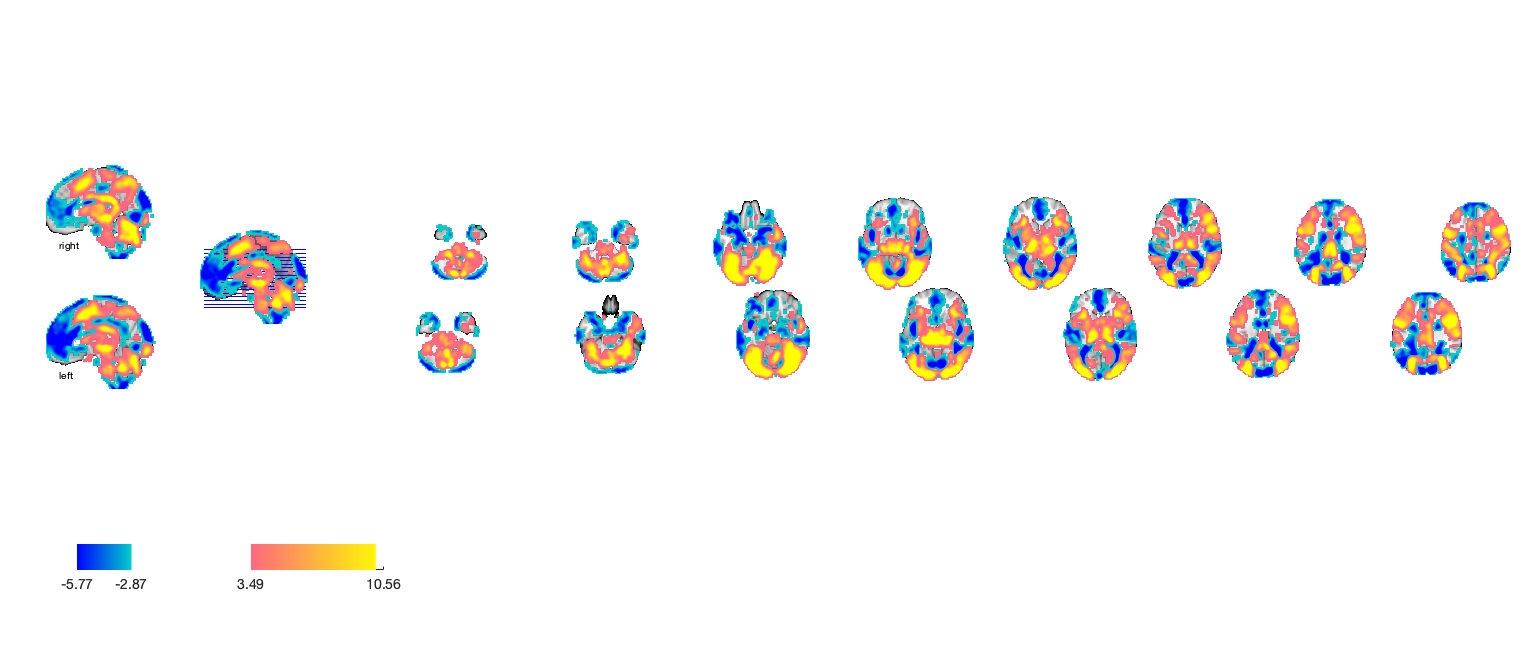

drawnow, snapnow;

#### Cognitive Cue only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low      testr_high     words_high  
    _________    _____________    __________    _____________

    -0.36182     {'trait'    }     0.49668      {'visual'   }
    -0.34604     {'rating'   }     0.39022      {'object'   }
    -0.32038     {'anxiety'  }     0.37536      {'objects'  }
    -0.31859     {'negative' }      0.3259      {'shape'    }
    -0.30936     {'disorder' }     0.32546      {'rotation' }
    -0.30848     {'affect'   }     0.31288      {'attention'}
    -0.30476     {'positive' }     0.28533      {'naming'   }
    -0.29948     {'personal' }      0.2826      {'letter'   }
    -0.29935     {'age'      }     0.28001      {'execution'}
    -0.29447     {'affective'}      0.2748      {'visually' }



#### Cognitive Cue only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.1327	-23.2943	0.0000	1.0000	
Cog Wholebrain	0.0282	8.4733	0.0000	1.0000	
Emo Wholebrain	0.1004	17.6561	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      -0.1327      0.005614    -23.638    2.2204e-15    -2.8252 
    {'Cog Wholebrain' }     0.028219     0.0033297     8.4749    2.7063e-12     1.0129 
    {'Emo Wholebrain' }      0.10035     0.0056492     17.765    2.2204e-15     2.1233 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {70×3 cell}
        text_han: {70×3 cell}
       point_han: {70×3 cell}
    star_handles: [9.0017 10.0017 11.0017]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.12763     0.0055127    -23.152    2.2204e-15    -2.7671 
    {'Cog Wholebrain' }     0.027651     0.0031356     8.8187    6.3827e-13      1.054 
    {'Emo Wholebrain' }     0.096844     0.0055568     17.428    2.2204e-15     2.0831 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {70×3 cell}
        text_han: {70×3 cell}
       point_han: {70×3 cell}
    star_handles: [12.0017 13.0017 14.0017]


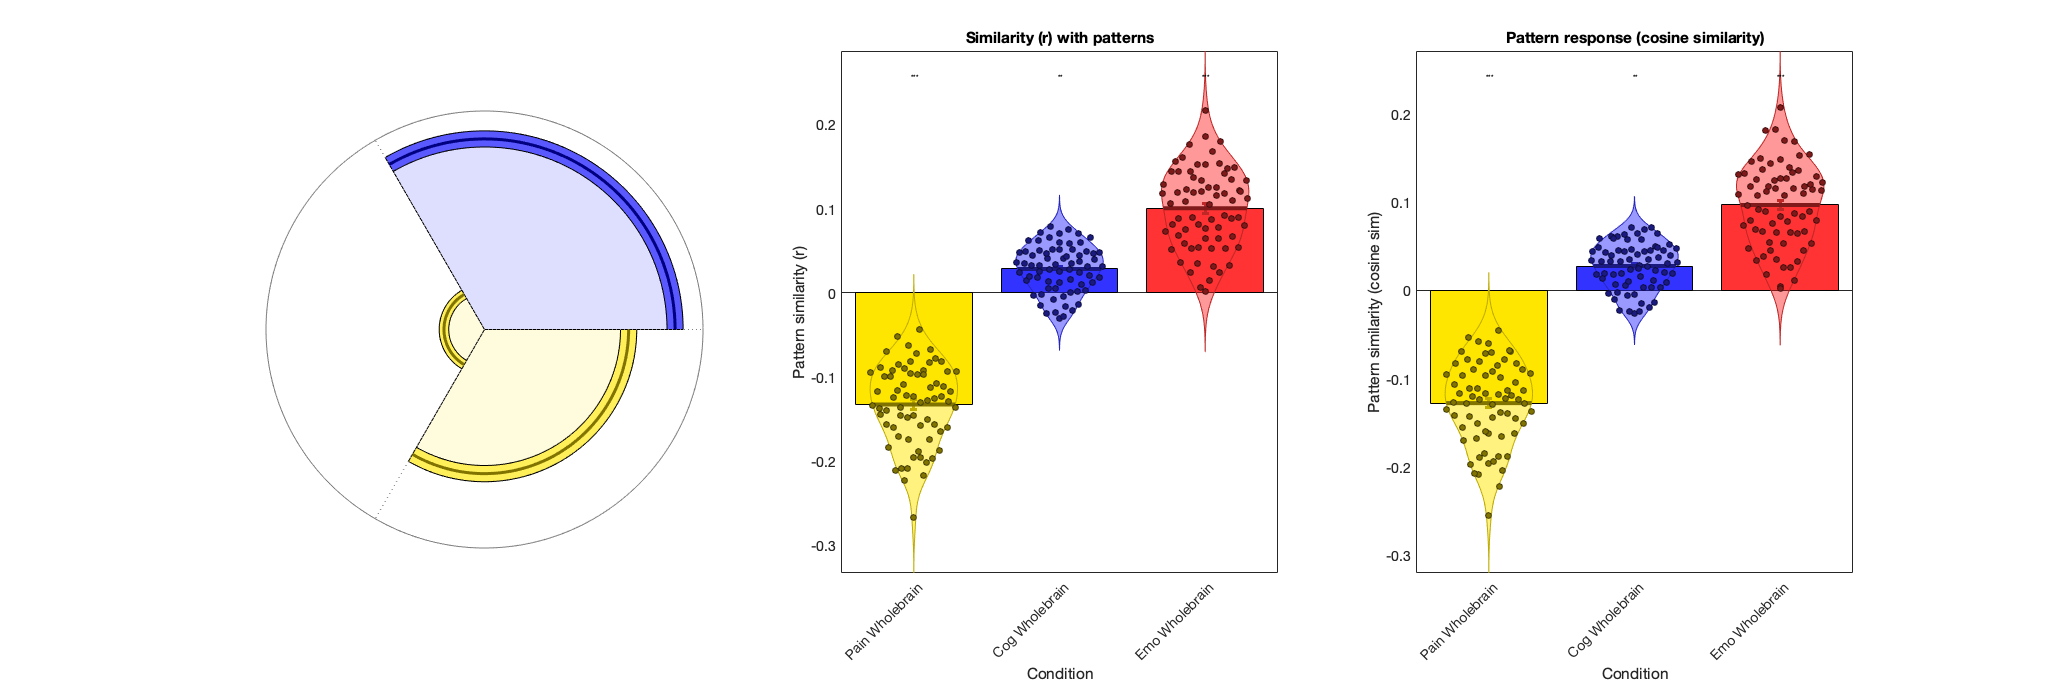

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;

% save html
pubdir = pwd;
pubfilename = 's03_PVC_cue_dummy_ROI.mlx';

p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
  'format', 'html', 'outputDir', pubdir, ...
  'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
htmlfile = publish(pubfilename, p);

Error using evalmxdom>instrumentAndRun (line 116)
Publishing a script that contains a publish function is not supported.

Error in evalmxdom (line 21)
[data,text,laste] = instrumentAndRun(file,cellBoundaries,imageDir,imagePrefix,options);

Error in publish